依赖[统一实验分析作图v18.0.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases/tag/v17.1.0)

行为学：比较image的几只小鼠，aud-water（naive-hit rate (A group)v.s. transfer hit rate(B group)), (leant hit(A group) v.s. final hit(B group))

DataSet=TransferLearning.FullCalcium;

统一实验分析作图v17.2.0已发布，<a href="https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases">立即更新</a>


%鼠内每个回合的细胞数都一样，因此没必要排除因细胞而重复的回合
CalciumPerformance=structfun(@(B)groupsummary(B,'Mouse','mean').mean_Behavior,DataSet.TableQuery(["Behavior","Mouse"],UniExp.ReadQueryTable(TransferLearning.ProjectPath('查询表.xlsx'),'Fig2C')),UniformOutput=false);

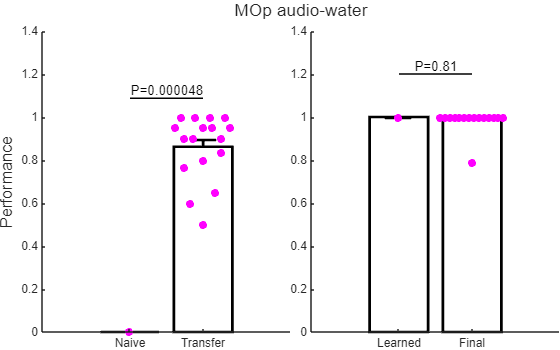

Colors=table;
CompareGroup=table;
figure;
Layout2=tiledlayout(1,2,TileSpacing='tight',Padding='tight');
nexttile(Layout2);
CompareGroup.GroupPair=["Naive","Transfer"];
CompareGroup.PLineOffset=0.1;
UniExp.BarScatterCompare(struct(Naive=CalciumPerformance.Naive_audio_water,Transfer=CalciumPerformance.Transfer_audio_water),CompareGroup);
box off
ylim([0,1.4]);
nexttile(Layout2);
CompareGroup.GroupPair=["Learned","Final"];
UniExp.BarScatterCompare(struct(Learned=CalciumPerformance.Learned_audio_water,Final=CalciumPerformance.Final_audio_water),CompareGroup);
box off
ylabel(Layout2,'Performance');
title(Layout2,'MOp audio-water');
MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Narrow);
print(TransferLearning.ProjectPath('Fig2C.svg'),'-dsvg');